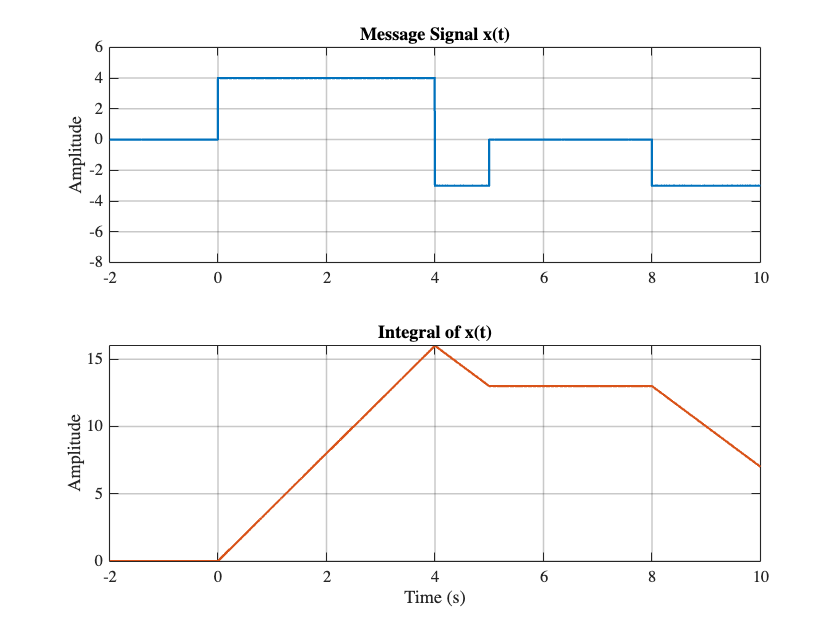

%% Communication Systems - Computer Assignment 2 - Question 2 (Corrected)
% Name: Vahid Hamzeh
% Student ID: 402101577
% Course: Communication Systems - Dr. Behroozi
% -------------------------------------------------------------------------
clc; clear; close all;

%% 1. Signal Definition & Integral [Source: 61, 64, 81]
% Parameters
Fs = 10000;             % Sampling Frequency = 10 kHz
Ts = 1/Fs;
t = -2:Ts:10;           % Time vector

% Define Unit Step Function
u = @(t) (t >= 0);

% Define Message Signal x(t)
x_t = 4*u(t) - 7*u(t-4) + 3*u(t-5) - 3*u(t-8);

% Calculate Integral using cumtrapz (Required by Source 81)
int_x_t = cumtrapz(t, x_t);

% Plot Part 1
figure('Name', 'Part 1: Message Signal Analysis', 'Color', 'w');
subplot(2,1,1);
plot(t, x_t, 'LineWidth', 1.5, 'Color', [0 0.4470 0.7410]);
title('Message Signal x(t)'); ylabel('Amplitude'); grid on; ylim([-8 6]);
subplot(2,1,2);
plot(t, int_x_t, 'LineWidth', 1.5, 'Color', [0.8500 0.3250 0.0980]);
title('Integral of x(t)'); xlabel('Time (s)'); ylabel('Amplitude'); grid on;


%% 2. & 3. Modulation & Validation [Source: 63, 65, 66]
fc = 500;               % Carrier Frequency = 500 Hz
kf = 60;                % Frequency Sensitivity (f_delta) = 60 Hz/V

% --- A) Manual Modulation (Formula Based) ---
% xc(t) = cos(2*pi*fc*t + 2*pi*kf * int(x(t)))
phase_manual = 2*pi*fc*t + 2*pi*kf * int_x_t;
xc_manual = cos(phase_manual);

% --- B) MATLAB Function Modulation (fmmod) ---
% Correction: fmmod 4th argument depends on the input signal scaling.
% Since x(t) is NOT normalized (amplitude varies), we pass kf directly.
xc_matlab = fmmod(x_t, fc, Fs, kf); 

% --- C) Error Analysis (Validation) ---
err_sig = xc_manual - xc_matlab;
max_err = max(abs(err_sig));
fprintf('Maximum Difference between Manual and fmmod: %.4e\n', max_err);

Maximum Difference between Manual and fmmod: 7.5380e-02


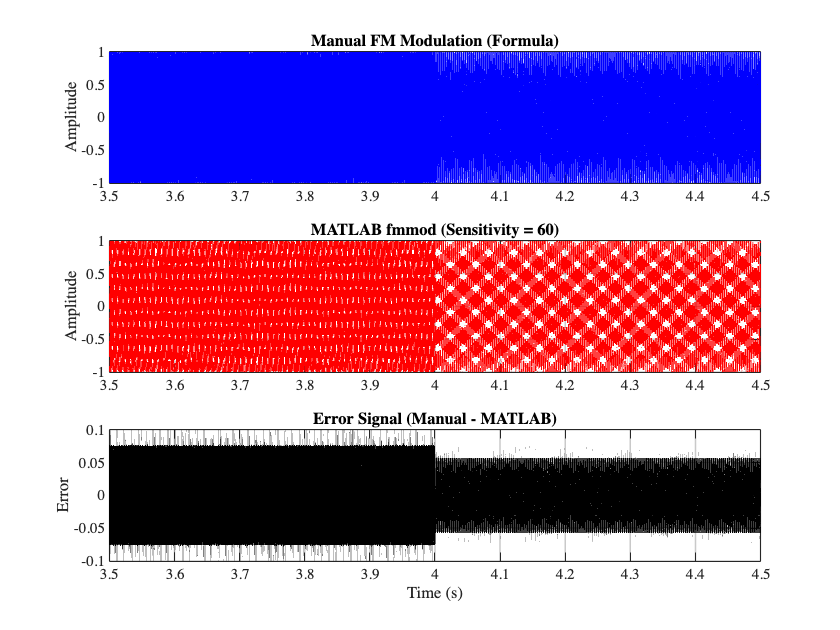


% Plot Parts 2 & 3 (Zoomed around t=4 where frequency jumps)
figure('Name', 'Part 2&3: Modulation & Validation', 'Color', 'w');
subplot(3,1,1);
plot(t, xc_manual, 'b', 'LineWidth', 1);
title('Manual FM Modulation (Formula)'); xlim([3.5 4.5]); grid on;
ylabel('Amplitude');

subplot(3,1,2);
plot(t, xc_matlab, 'r--', 'LineWidth', 1);
title(['MATLAB fmmod (Sensitivity = ' num2str(kf) ')']); xlim([3.5 4.5]); grid on;
ylabel('Amplitude');

subplot(3,1,3);
plot(t, err_sig, 'k', 'LineWidth', 1);
title('Error Signal (Manual - MATLAB)'); xlim([3.5 4.5]); grid on;
xlabel('Time (s)'); ylabel('Error');

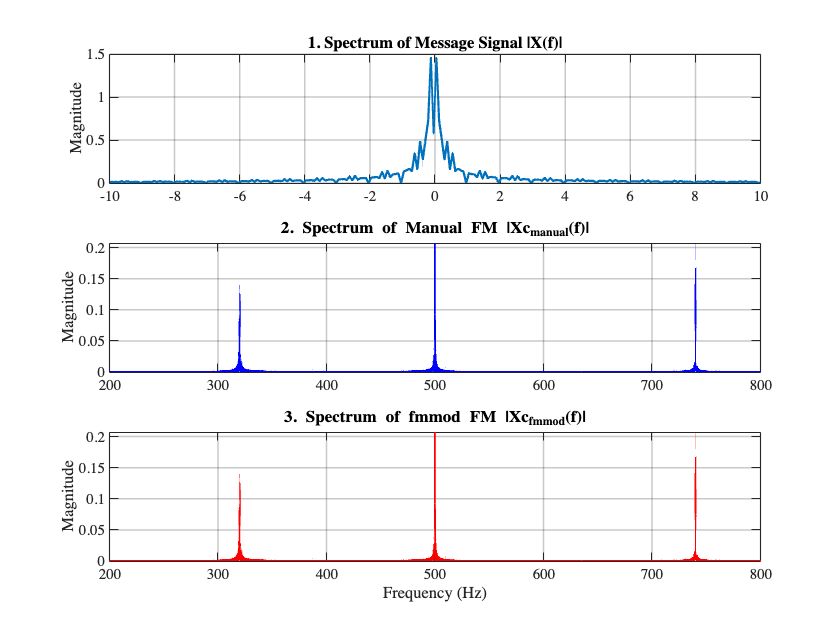


%% 4. Frequency Spectrum Comparison [Source: 67]
L = length(t);
f = (-L/2 : L/2 - 1)*(Fs/L); % Frequency vector

X_f = fftshift(fft(x_t))/L;
Xc_manual_f = fftshift(fft(xc_manual))/L;
Xc_matlab_f = fftshift(fft(xc_matlab))/L;

figure('Name', 'Part 4: Spectra Comparison', 'Color', 'w');

% Plot 1: Message Spectrum
subplot(3,1,1);
plot(f, abs(X_f), 'LineWidth', 1.5, 'Color', [0 0.4470 0.7410]);
title('1. Spectrum of Message Signal |X(f)|'); 
xlim([-10 10]); grid on; ylabel('Magnitude');

% Plot 2: Spectrum of Manual FM
subplot(3,1,2);
plot(f, abs(Xc_manual_f), 'LineWidth', 1.2, 'Color', 'b');
title('2. Spectrum of Manual FM |Xc_{manual}(f)|'); 
xlim([200 800]); grid on; ylabel('Magnitude');

% Plot 3: Spectrum of fmmod FM (Should now MATCH Plot 2)
subplot(3,1,3);
plot(f, abs(Xc_matlab_f), 'LineWidth', 1.2, 'Color', 'r', 'LineStyle', '-');
title('3. Spectrum of fmmod FM |Xc_{fmmod}(f)|'); 
xlim([200 800]); grid on; xlabel('Frequency (Hz)'); ylabel('Magnitude');


%% 5. Carson's Rule Calculation [Source: 68]
% BW = 2 * (Delta_f + B_m)
% Now we calculate Delta_f correctly for the report:
max_amp = max(abs(x_t)); % = 4
Delta_f = kf * max_amp;  % = 240 Hz
B_m_est = 2;             % Estimated bandwidth of x(t)

BW_Carson = 2 * (Delta_f + B_m_est);
modulation_index = Delta_f / B_m_est;

fprintf('\n--- Part 5: Carson''s Rule ---\n');


--- Part 5: Carson's Rule ---


fprintf('Frequency Sensitivity (kf): %.2f Hz/V\n', kf);

Frequency Sensitivity (kf): 60.00 Hz/V


fprintf('Peak Frequency Deviation (Delta f): %.2f Hz\n', Delta_f);

Peak Frequency Deviation (Delta f): 240.00 Hz


fprintf('Estimated Message Bandwidth (Bm): %.2f Hz\n', B_m_est);

Estimated Message Bandwidth (Bm): 2.00 Hz


fprintf('Carson Bandwidth: %.2f Hz\n', BW_Carson);

Carson Bandwidth: 484.00 Hz


%% 6. Slope Detector Design & Phase Bounds [Source: 70-80]

% --- A) Calculate Phase Bounds [Source: 72] ---

% 1. Phase Deviation (Correct for FM Analysis)
% This is the phase strictly due to the message signal x(t).
% Formula: phi_dev(t) = 2 * pi * kf * integral(x(t))
phase_deviation = 2 * pi * kf * int_x_t;
min_dev = min(phase_deviation);
max_dev = max(phase_deviation);

% 2. Total Phase (What your friend calculated)
% This includes the carrier term which grows constantly with time.
% Formula: phi_total(t) = 2*pi*fc*t + phi_dev(t)
total_phase = 2 * pi * fc * t + phase_deviation;
min_total = min(total_phase);
max_total = max(total_phase);

fprintf('\n--- Part 6: Phase Bounds Analysis ---\n');


--- Part 6: Phase Bounds Analysis ---


fprintf('1. Phase Deviation (Signal Component):\n');

1. Phase Deviation (Signal Component):


fprintf('   Min: %.4f rad, Max: %.4f rad (Use this for Report)\n', min_dev, max_dev);

   Min: 0.0000 rad, Max: 6031.8013 rad (Use this for Report)


fprintf('2. Total Phase (Including Carrier):\n');

2. Total Phase (Including Carrier):


fprintf('   Min: %.4f rad, Max: %.4e rad \n', min_total, max_total);

   Min: -6283.1853 rad, Max: 3.4055e+04 rad 


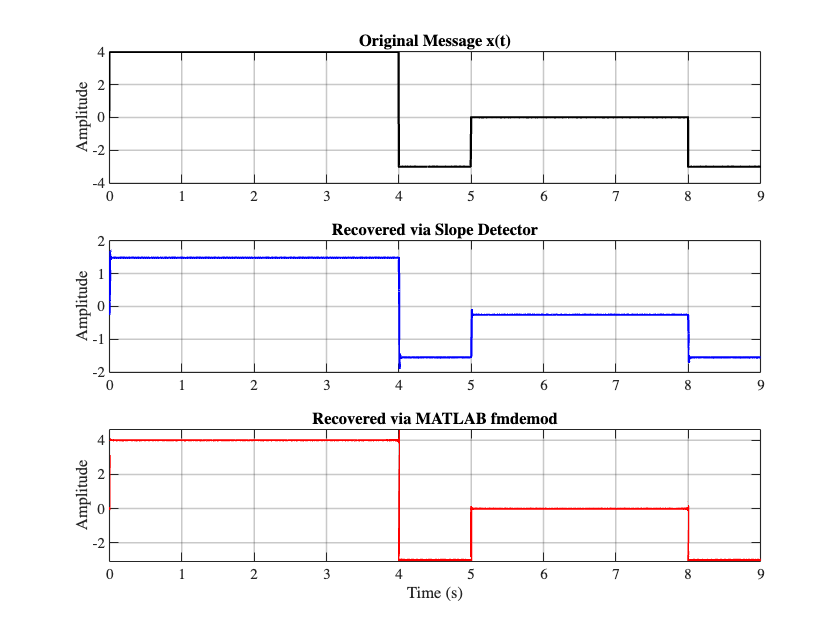


% --- B) Slope Detector Implementation ---

% Step 1: Differentiator (using Central Difference Formula) [Source: 80]
dx_c = zeros(size(xc_manual));
for n = 2:length(xc_manual)-1
    dx_c(n) = (xc_manual(n+1) - xc_manual(n-1)) / (2*Ts);
end

% Step 2: Envelope Detector (Absolute Value) [Source: 75]
rectified = abs(dx_c);

% Step 3: Low Pass Filter [Source: 76]
% Cutoff > B_m (approx 2Hz) and << Carrier (500Hz).
fc_lpf = 80; 
[b, a] = butter(4, fc_lpf/(Fs/2)); 
y_slope = filter(b, a, rectified);

% Step 4: Post-Processing (Remove DC and Scale)
y_slope_ac = y_slope - mean(y_slope); 
scaling_factor = max(abs(x_t)) / max(abs(y_slope_ac));
recovered_slope = y_slope_ac * scaling_factor;

%% 7. Comparison with fmdemod [Source: 82, 83]
z_matlab = fmdemod(xc_manual, fc, Fs, kf); % Corrected fmdemod usage

figure('Name', 'Part 6 & 7: Demodulation Comparison', 'Color', 'w');
subplot(3,1,1);
plot(t, x_t, 'k', 'LineWidth', 1.5);
title('Original Message x(t)'); xlim([0 9]); grid on; ylabel('Amplitude');

subplot(3,1,2);
plot(t, recovered_slope, 'b', 'LineWidth', 1.5);
title('Recovered via Slope Detector'); xlim([0 9]); grid on; ylabel('Amplitude');

subplot(3,1,3);
plot(t, z_matlab, 'r', 'LineWidth', 1.5);
title('Recovered via MATLAB fmdemod'); xlim([0 9]); grid on;
xlabel('Time (s)'); ylabel('Amplitude');